# **drawDonut**

# **fillDonut**

Draw or fill donut i.e, two concentric circles with given diameter.

## Description

Donut is IGES flash entity (type 125),  form number 3 (see [1], pp 120-123).

## Syntax

drawDonut(d1,d2,xc,yc)

drawDonut(d1,d2,xc,yc,LineSpec)

drawDonut(d1,d2,xc,yc,'-np',np)

p = drawDonut(__)

fillDonut(c1,c2,__)

### Description

drawDonut((d1,d2,xc,yc) draw concentric circles wit diameters d1 and d2 and center in point (xc,yc).

drawDonut(wd,ht,LineSpec)  sets the line style, line width, and color.

p = drawDonut(__) returns structure with output data.

### Method

drawDonut call the function **evalCircle**.

The curve is plotted by MATLAB function [plot](https://www.mathworks.com/help/matlab/ref/plot.html).

## Arguments

### Input Arguments

**c1, c2 **- fill color

**d1 **- diameter of outer circle

**d2 **- diameter of inner circle

**xc       **- circle center

**yc       **- 

### Optional Name-Value Pair Input Arguments

**'-np',np** - number of points on each circle

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure  with fields

- p.style - line style 

- p.width - line width 

- p.color - line color

## Examples

### Example 1

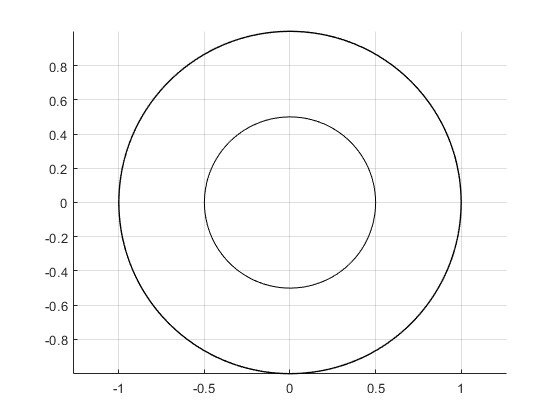

figure
hold on
axis equal
% close polygon
drawDonut( 2, 1,0,0);
grid on

#### **Example 2**

figure
axis equal
hold on
p=drawDonut(2,1,1,1,'r:')

p = struct with fields:
       xk: [0 2 1 1 1]
       yk: [1 1 0 2 1]
    color: [1 0 0]


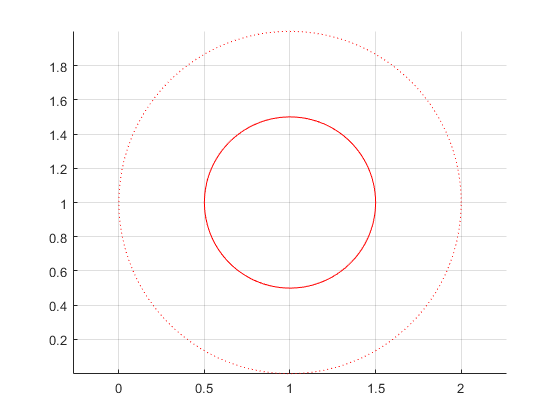

grid on

#### **Example 3**

figure
axis equal
hold on
p=drawDonut(4,3,0,0,'LineWidth',2,'-np',10)

p = struct with fields:
       xk: [-2 2 0 0 0]
       yk: [0 0 -2 2 0]
    color: [0 0.4470 0.7410]


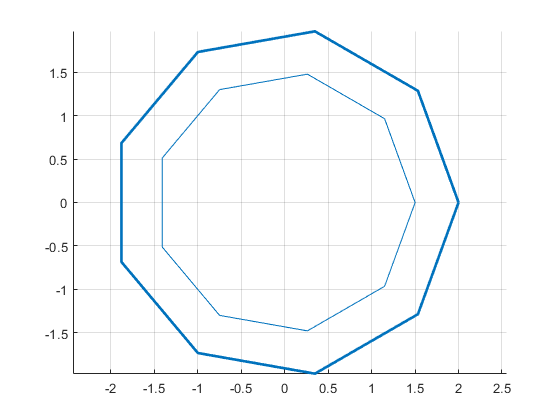

grid on

#### **Example 3**

figure
axis equal
hold on
p=fillDonut('r','y',4,3,0,0)

p = struct with fields:
    xk: [-2 2 0 0]
    yk: [0 0 -2 2]


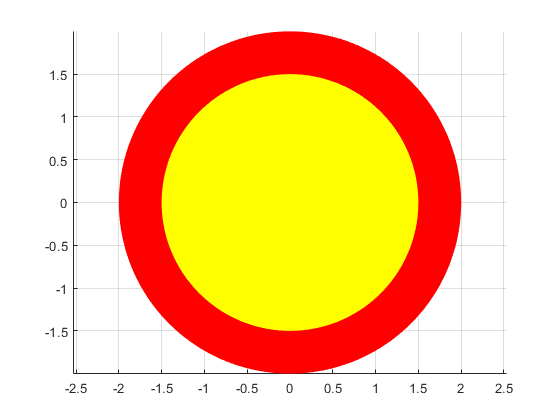

grid on

## See also

## References

  [1] [IGES Initial Graphics Exchange Specification IGES 5.3](http://paulbourke.net/dataformats/iges/IGES.pdf)